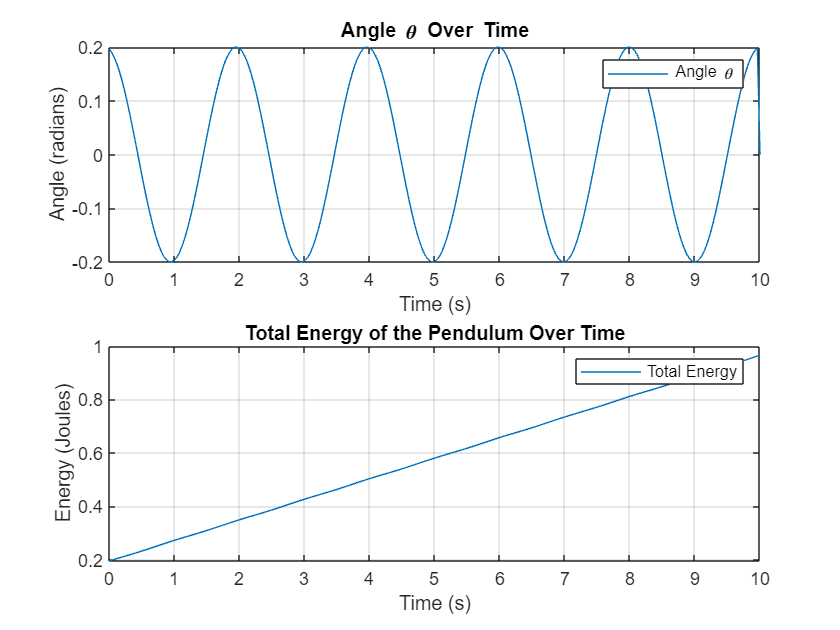

g = 9.81;                           % acceleration due to gravity in m/s^2
length = 1.0;                       % length of pendulum in meters
mass = 1.0;                         % mass of pendulum
time_step = 0.04;                   % time step in seconds
total_time = 10.0;                  % total time for simulation in seconds
num_steps = total_time / time_step; % number of steps in the simulation

% Initial conditions
theta = 0.2; % initial angle in radians
omega = 0.0; % initial angular velocity in radians/s

% Arrays to hold time evolution
thetas = zeros(1, num_steps);
omegas = zeros(1, num_steps);
energies = zeros(1, num_steps);
times = linspace(0, total_time, num_steps);

% Calculate initial energy
kinetic_energy = 0.5 * mass * (length * omega)^2;
potential_energy = mass * g * length * (1 - cos(theta));
energies(1) = kinetic_energy + potential_energy; % Initial energy stored

% Simulation using the Euler-Cromer method
for i = 1:num_steps-1
    omega = omega - (g / length) * theta * time_step; % Update angular velocity
    theta = theta + omega * time_step;               % Update angle using the new angular velocity

    thetas(i) = theta;                               % Store values
    omegas(i) = omega;
    
    kinetic_energy = 0.5 * mass * (length * omega)^2;
    potential_energy = mass * g * length * (1 - cos(theta));
    total_energy = kinetic_energy + potential_energy;

    % Update energy using the formula from equation 
    energies(i + 1) = energies(i) + 0.5 * mass * g * (omega^2 + (g/length) * theta^2) * time_step^2;
end

figure;

% Subplot for angle theta over time
subplot(2, 1, 1);
plot(times, thetas, 'DisplayName', 'Angle \theta');
xlabel('Time (s)');
ylabel('Angle (radians)');
title('Angle \theta Over Time');
legend;
grid on;

% Plotting the total energy over time
subplot(2, 1, 2);
plot(times, energies, 'DisplayName', 'Total Energy');
xlabel('Time (s)');
ylabel('Energy (Joules)');
title('Total Energy of the Pendulum Over Time');
legend;
grid on;